% Define suspension system equation

% Define specified parameters

% c is the damping coefficient in Ns/m
c = 1.5*10^3;
% k is the spring constant in N/m
k = 1.5*10^4;
% m is mass in kg
m = 3.6*10^3;

% Y0 is the initial displacement in metres
y0 = 0.3;

% Define calculated values
n = c/(2*m);
springConstPerMetre = k/m;
dampCoPerMass = c^2 / (4*m^2);

assert(springConstPerMetre > dampCoPerMass)

rootD = sqrt(springConstPerMetre - dampCoPerMass);

% Define symbol t for use in function
syms t
% Define function
systemFunc(t) = exp(-n*t) * y0 * (cos(rootD*t) + (n/rootD)*sin(rootD*t));




% Plot graph

% define values for x
x1 = 0:0.01:10;

% Pass values of into function and plot
plot(x1,systemFunc(x1),'-b')

% Set x axis to strike throught origin
ax = gca;
ax.XAxisLocation ='origin'

ax =   Axes with properties:

             XLim: [0 10]
             YLim: [-0.3000 0.3000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


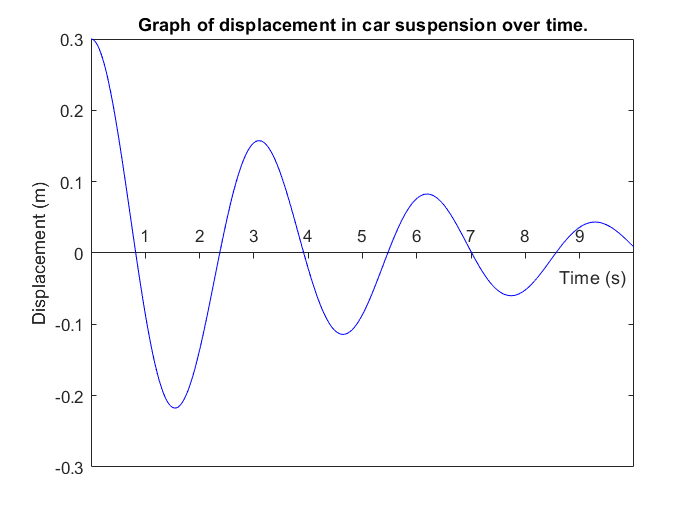



% Set x and y labels
xlabel("Time (s)")
ylabel("Displacement (m)")

% Give graph a title
title("Graph of displacement in car suspension over time.")

% % Set minimum error value used to find root.
error = 1E-3

error = 1.0000e-03


% Identify the first 3 roots as around 0.5, 2, 3.7
% Calculate roots iteratively using the Newton-Raphson second method.
root1 = double(findRoot(0.5, systemFunc, error))

root1 = 0.8239

root2 = double(findRoot(2, systemFunc, error))

root2 = 2.3710

root3 = double(findRoot(3.7, systemFunc, error))

root3 = 3.9182

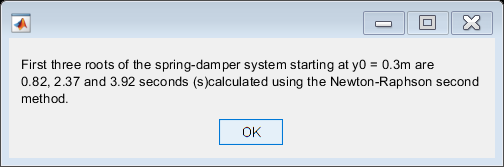


% Print the first 3 roots.
msgbox(sprintf(['First three roots of the spring-damper system starting ' ...
    'at y0 = 0.3m are %2.2f, %2.2f and %2.2f seconds (s)' ...
    'calculated using the Newton-Raphson second method.'],root1,root2,root3))

% Experimental data

% Create the values for time.
time = 2.6:0.05:3.1

time =     2.6000    2.6500    2.7000    2.7500    2.8000    2.8500    2.9000    2.9500    3.0000    3.0500    3.1000



% Experimental displacement data
experimentDisp = [0.074, 0.094, 0.106, 0.113, 0.127, 0.145, 0.145, 0.148, 0.154, 0.162, 0.158]

experimentDisp =     0.0740    0.0940    0.1060    0.1130    0.1270    0.1450    0.1450    0.1480    0.1540    0.1620    0.1580


% Expected displacement data calculated using the given function.
calculatedDisp = double(systemFunc(time))

calculatedDisp =     0.0787    0.0932    0.1064    0.1183    0.1287    0.1376    0.1449    0.1505    0.1545    0.1568    0.1574



[R,e] = calcErrorAndDetermination(experimentDisp,calculatedDisp)

meanY = 0.1296

N = 11

totalSumSquares = 0.0075

residualSumSquares = 0.0085

R = 0.8815

diffSum = 1.4228e-04

e = 0.0040

R = 0.8815

e = 0.0040

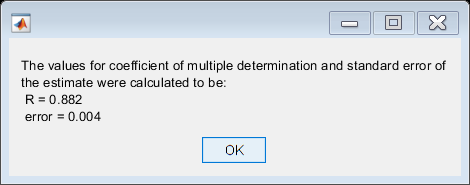


msgbox(sprintf(['The values for coefficient of multiple determination and ' ...
    'standard error of the estimate were calculated to' ...
    ' be: \n R = %1.3f \n error = %1.3f'],R,e))

% Plot the experimental results data

figure

% Plot experimental displacemet data as a scatter graph.
plot(time,experimentDisp,'ko')

% Allow other plots to draw over the graph.
hold on

% Set x and y labels
xlabel("Time (s)")
ylabel("Displacement (m)")

% Give graph a title
title("Graph experimental data for the displacement in car suspension over time.")

% Define an finer array of the same ranges as time.
t2 = 2.6:0.01:3.1

t2 =     2.6000    2.6100    2.6200    2.6300    2.6400    2.6500    2.6600    2.6700    2.6800    2.6900    2.7000    2.7100    2.7200    2.7300    2.7400    2.7500    2.7600    2.7700    2.7800    2.7900    2.8000    2.8100    2.8200    2.8300    2.8400    2.8500    2.8600    2.8700    2.8800    2.8900    2.9000    2.9100    2.9200    2.9300    2.9400    2.9500    2.9600    2.9700    2.9800    2.9900    3.0000    3.0100    3.0200    3.0300    3.0400    3.0500    3.0600    3.0700    3.0800    3.0900



% From theory saturation curve graph points are equal to 
% the inverse of a corresponding linear graph.

inverseTime = 1./time

inverseTime =     0.3846    0.3774    0.3704    0.3636    0.3571    0.3509    0.3448    0.3390    0.3333    0.3279    0.3226


inverseExpDisp = (1./experimentDisp)

inverseExpDisp =    13.5135   10.6383    9.4340    8.8496    7.8740    6.8966    6.8966    6.7568    6.4935    6.1728    6.3291




% Calculate the linear regression of the inverse values.
[a,b] = linear_regression(inverseTime,inverseExpDisp)

x_sum = 3.8716

y_sum = 89.8547

xy_sum = 32.0546

x_square_sum = 1.3669

N = 11

denom = 0.0465

a = -27.5801

b = 101.5695

a = -27.5801

b = 101.5695


% Alpha is equal to the inverse of a.
Alpha = 1/a

Alpha = -0.0363

% Beta is equal to b/a.
Beta = b/a

Beta = -3.6827


% Calculate the saturation curve using the equation (Alpha*x)/(Beta+x)
saturationCurve = (Alpha * t2)./(Beta+t2)

saturationCurve =     0.0871    0.0882    0.0894    0.0906    0.0918    0.0930    0.0943    0.0956    0.0969    0.0983    0.0996    0.1010    0.1024    0.1039    0.1054    0.1069    0.1085    0.1100    0.1117    0.1133    0.1150    0.1167    0.1185    0.1203    0.1222    0.1241    0.1260    0.1280    0.1301    0.1322    0.1343    0.1365    0.1388    0.1411    0.1435    0.1460    0.1485    0.1511    0.1538    0.1565    0.1593    0.1622    0.1652    0.1683    0.1715    0.1748    0.1782    0.1817    0.1853    0.1890


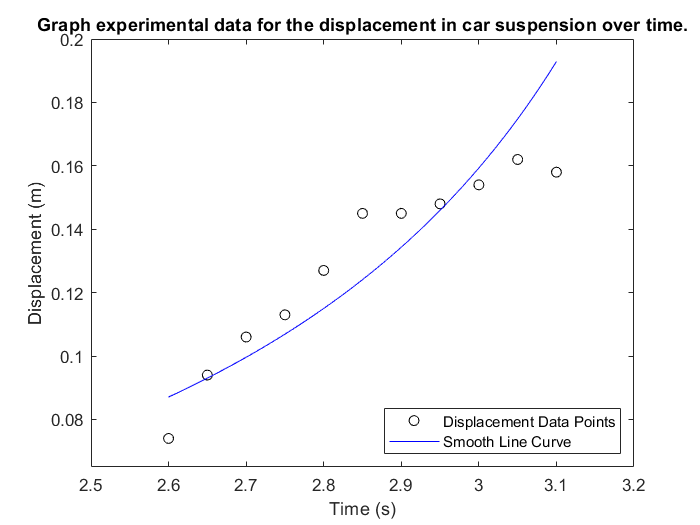

plot(t2,saturationCurve,'b')

% Adjust the range limits so all scatter points are visible.
xlim([2.5,3.2])
ylim([0.065,0.2])
% Define the legend of the graph.
legend('Displacement Data Points','Saturation Line Curve','Location',"southeast")

function [R,e] = calcErrorAndDetermination(y,g)
% Calculate the coefficient of multiple determination and 
% standard error of the estimate 
% Where y and g are arrays of the same length
% Where y is the found value and g is the predicted/calculated
% Returns arrays where R is the coefficient of multiple determination and
% e is the standard error of the estimate.

% Assert that inputs are the same size to prevent error and ensure
% a correct calculation.
    assert(length(y) == length(g))
    
    meanY = mean(y)
%     Calculate the total number of items
    N = length(y)
    
% Calculate the total sum of square and residual sum
    totalSumSquares = sum((g - meanY).^2)
    residualSumSquares =sum((y - meanY).^2)
    
% Calculate the coefficient of multiple determination
    R = (totalSumSquares/residualSumSquares)     
    
% Calculate the standard error of the estimate
    diffSum = sum((y-g).^2 )
    e = sqrt( diffSum/ (N-2) )
end    
function [a,b] = linear_regression(x,y)
% Calculate the linear rengression using two arrays.
    assert(length(x) == length(y))
    
% Calculate the sum of y,x,xy and x^2.
    x_sum = sum(x)
    y_sum = sum(y)
    xy_sum = sum(x.*y)
    x_square_sum = sum(x.^2)
    
% Get the length of the arrays
    N = length(x)
    
% To avoid rewriting code calculate the shared denominator.
    denom = N*x_square_sum - x_sum^2
    
% Calculate a and b.
    a = (y_sum*x_square_sum - xy_sum*x_sum) / denom
    b = (N*xy_sum - y_sum*x_sum) / denom 

end
function x = findRoot(x0,func,error)
% Iteratively calculate the root to within a certain error using 
% the newton rhapson formula.

% Check required error is greater than 0
    assert(error > 0)
    
%     Find the first estimate for x
    x = newtonRhapson_2(x0,func);
%     Use the new value for x to find the height at that point
    y = func(x);
    
%     While height is not within the margin for error then loop
    while abs(y) > error
%         Calculate a new estimate for x
        x = double(newtonRhapson_2(x,func));
%         Calculate the height at that point
        y = double(func(x));
    end
end

function x = newtonRhapson_2(x0,func)
% Implementation of Newton Rhapson's second equation.
% Note it would be more efficicient to calculate the derivatives once and 
% inline this function into findRoot, however I believe this is easier to
% read.

% Calulate the first derivative of the given function
    derFunc = diff(func);
% Calculate the second derivative of the given function
    secondDerFunc  = diff(func,2);
    
% Calculate the slope when x = x0
    slope = derFunc(x0);
% Calculate the derivative of the slope when x = x0
    derSlope = secondDerFunc(x0);
    
    x = x0 + (derSlope/(2*slope) - slope/func(x0))^-1;
end